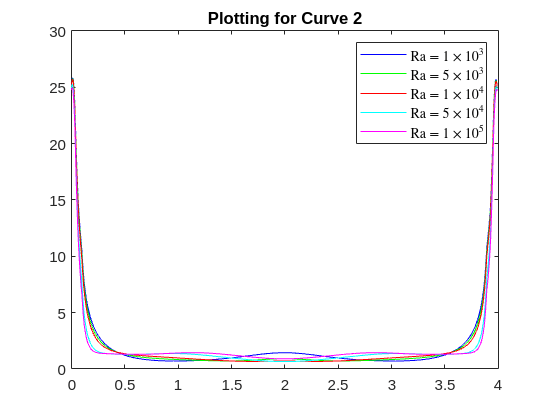

clear all
file1 = fopen('Nu1.txt','r');
file2 = fopen('Nu2.txt','r');

dat = textscan(file1,'%f %f');
Nu1 = cell2mat(dat);
dat2 = textscan(file2,'%f %f');
Nu2 = cell2mat(dat2);

cellS1 = size(Nu1,1)/5;
cellS2 = size(Nu2,1)/5;
maxS = max(cellS1,cellS2);
minS = min(cellS1,cellS2);
X1 = zeros(maxS,6);
X2 = zeros(maxS,6);

X1(1:cellS1,:) = [Nu1(1:cellS1,1),Nu1(1:cellS1,2),Nu1(cellS1+1:2*cellS1,2),Nu1(2*cellS1+1:3*cellS1,2),Nu1(3*cellS1+1:4*cellS1,2),Nu1(4*cellS1+1:5*cellS1,2)];
X2 = [Nu2(1:cellS2,1),Nu2(1:cellS2,2),Nu2(cellS2+1:2*cellS2,2),Nu2(2*cellS2+1:3*cellS2,2),Nu2(3*cellS2+1:4*cellS2,2),Nu2(4*cellS2+1:5*cellS2,2)];
X1(1:maxS,1) = Nu2(1:cellS2,1);

figure(2)
plot(X1(1:cellS1,1)',X1(1:cellS1,2)','b')
hold on
plot(X1(1:cellS1,1)',X1(1:cellS1,3)','g')
hold on
plot(X1(1:cellS1,1)',X1(1:cellS1,4)','r')
hold on
plot(X1(1:cellS1,1)',X1(1:cellS1,5)','c')
hold on
plot(X1(1:cellS1,1)',X1(1:cellS1,6)','m')
hold off

title('Plotting for Curve 2')
legend('Ra =  $1\times10^3$','Ra =  $5\times10^3$','Ra =  $1\times10^4$','Ra =  $5\times10^4$','Ra =  $1\times10^5$','Interpreter','Latex')

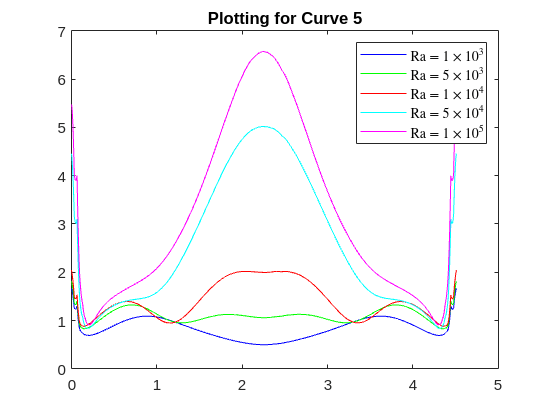


figure(3)
plot(X2(1:cellS2,1)',X2(1:cellS2,2)','b')
hold on
plot(X2(1:cellS2,1)',X2(1:cellS2,3)','g')
hold on
plot(X2(1:cellS2,1)',X2(1:cellS2,4)','r')
hold on
plot(X2(1:cellS2,1)',X2(1:cellS2,5)','c')
hold on
plot(X2(1:cellS2,1)',X2(1:cellS2,6)','m')
hold off

title('Plotting for Curve 5')
legend('Ra =  $1\times10^3$','Ra =  $5\times10^3$','Ra =  $1\times10^4$','Ra =  $5\times10^4$','Ra =  $1\times10^5$','Interpreter','Latex')

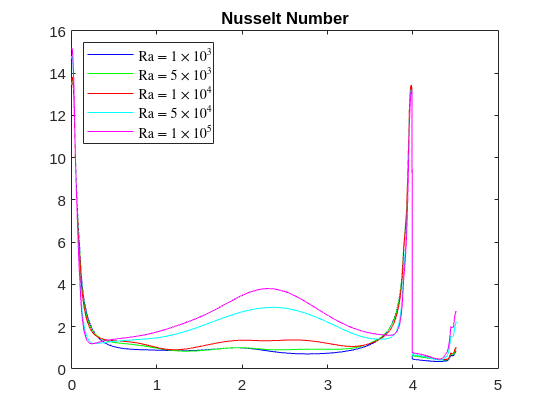


X3 = (X1+X2)./2;

figure(3)

plot(X3(1:maxS,1)',X3(1:maxS,2)','b')
hold on
plot(X3(1:maxS,1)',X3(1:maxS,3)','g')
hold on
plot(X3(1:maxS,1)',X3(1:maxS,4)','r')
hold on
plot(X3(1:maxS,1)',X3(1:maxS,5)','c')
hold on
plot(X3(1:maxS,1)',X3(1:maxS,6)','m')
hold off
title('Nusselt Number')
legend('Ra =  $1\times10^3$','Ra =  $5\times10^3$','Ra =  $1\times10^4$','Ra =  $5\times10^4$','Ra =  $1\times10^5$','Interpreter','Latex','Location',"northwest")